# Problema n°3

## Consigna

Se tiene una carga que puede expresarse como la siguiente serie seno:


$$P\left(t\right)=\sum_{n=1} {\;b}_n *\sin \left(\bar{w_n } *t\right)$$


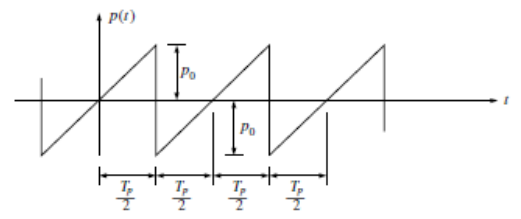

Donde:


$$b_n =-\frac{2\textrm{Po}}{n\pi }{\left(-1\right)}^n$$


Graficar la carga y la respuesta permanente de un sistema de un grado de libertad a esa carga para un período completo, considerando sólo los pirmeros 4 términos de la serie y evaluando a incrementos de tiempo dado por:

     $\bar{w_n } *\Delta t=30\degree$.

Admita que el sistema no tiene amortiguamiento y:


$$k=1\;\frac{N}{m}$$
     
$$m=1\;\textrm{kg}$$
       
$$\textrm{Po}=1\;N$$
        
$$\frac{\textrm{Tp}}{T}=\frac{4}{3}$$


## Respuesta para comparar

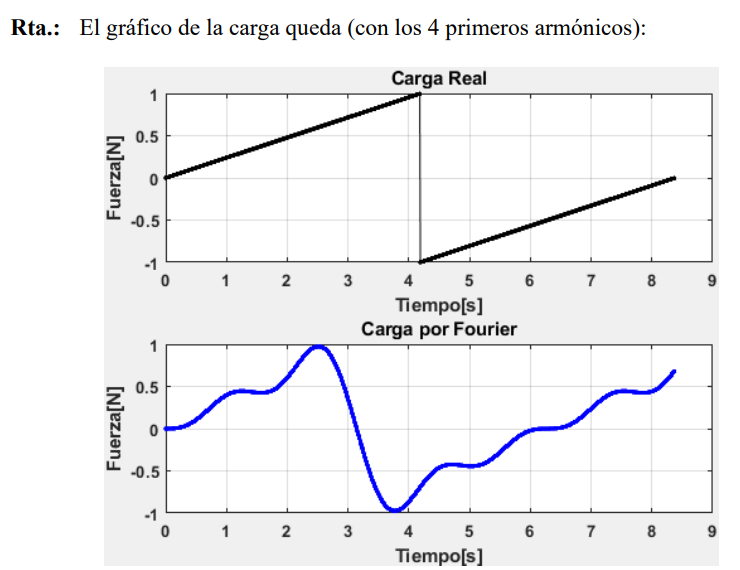

## Resolución

Datos del sistema con un gdl

k=1;      %[N/m]

m=1;      %[kg]

wn=sqrt(k/m);

T=2*pi/wn 

T = 6.2832

Datos de la carga

Po = 1      %[N]

Po = 1

Tp = T*4/3 %[s]

Tp = 8.3776

%Frecuencia de la carga
wp = 2*pi/Tp    %[rad/s]

wp = 0.7500

Tengo que obtener cuánto será el paso $\Delta t$ para poder generar el vector t. Para ello:


$$\begin{array}{l}
w_p *\Delta t*\frac{180\degree }{\pi }=30\degree \\
\Delta t=\frac{30*\pi }{180*w_p }
\end{array}$$


deltaT = 30*pi/(180*wp)

deltaT = 0.6981

t = 0:deltaT:10

t =          0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832    6.9813    7.6794    8.3776    9.0757    9.7738


### Gráfica de la carga

%Número de armónicos
N=4;
P=0;

for n=1:N
    %Coeficientes bn
    bn = -2 * Po * (-1).^n ./ (n*pi);
    P = P + bn*sin(n*wp*t);
end
P

P =          0    0.1170    0.4135    0.4244    0.6892    0.9440    0.0000   -0.9440   -0.6892   -0.4244   -0.4135   -0.1170         0    0.1170    0.4135



%f = figure('Visible', 'on') %Con esto hago que se genere una ventana externa con los gráficos

subplot(3,1,1)
plot(t,P)
hold on
scatter(t,P)
hold off
title('P(t) con Fourier usando 4 armónicos')
xlabel('Tiempo')
ylabel('P(t)', 'Rotation', 0)
grid on

### Gráfica de la respuesta del sistema

Podemos obtener la respuesta en el tiempo sabiendo que para un sistema no amortiguado:

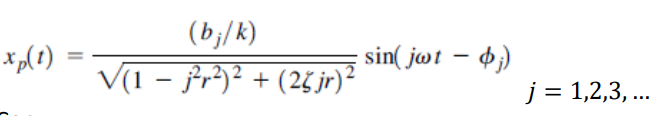

x=0

x = 0

r=wp/wn

r = 0.7500

zitta = 0;
for n=1:N
    %Coeficientes bn
    bn = -2*Po*(-1).^n./(n*pi);
    phi_n = atan(2*zitta*(n*r)/(1-(n*r)^2));
    x = x + (bn/k)/sqrt((1-n^2*r^2)^2)*sin(n*wp*t-phi_n);
end

subplot(3,1,2)
plot(t,x)
hold on
scatter(t,x)
hold off
title('Respuesta del sistema')
xlabel('Tiempo')
ylabel('X(t)', 'Rotation', 0)
grid on

### Gráficas superpuestas

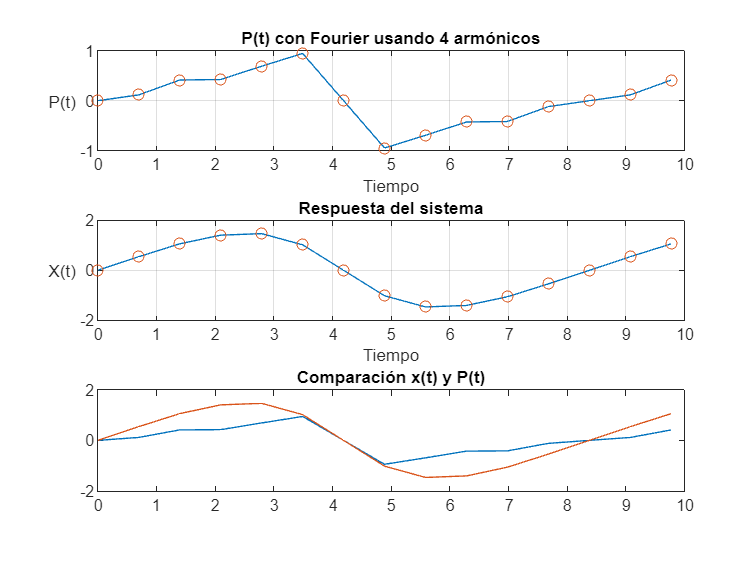

subplot(3,1,3)
plot(t,P)
title("Comparación x(t) y P(t)")
hold on
plot(t,x)
hold off